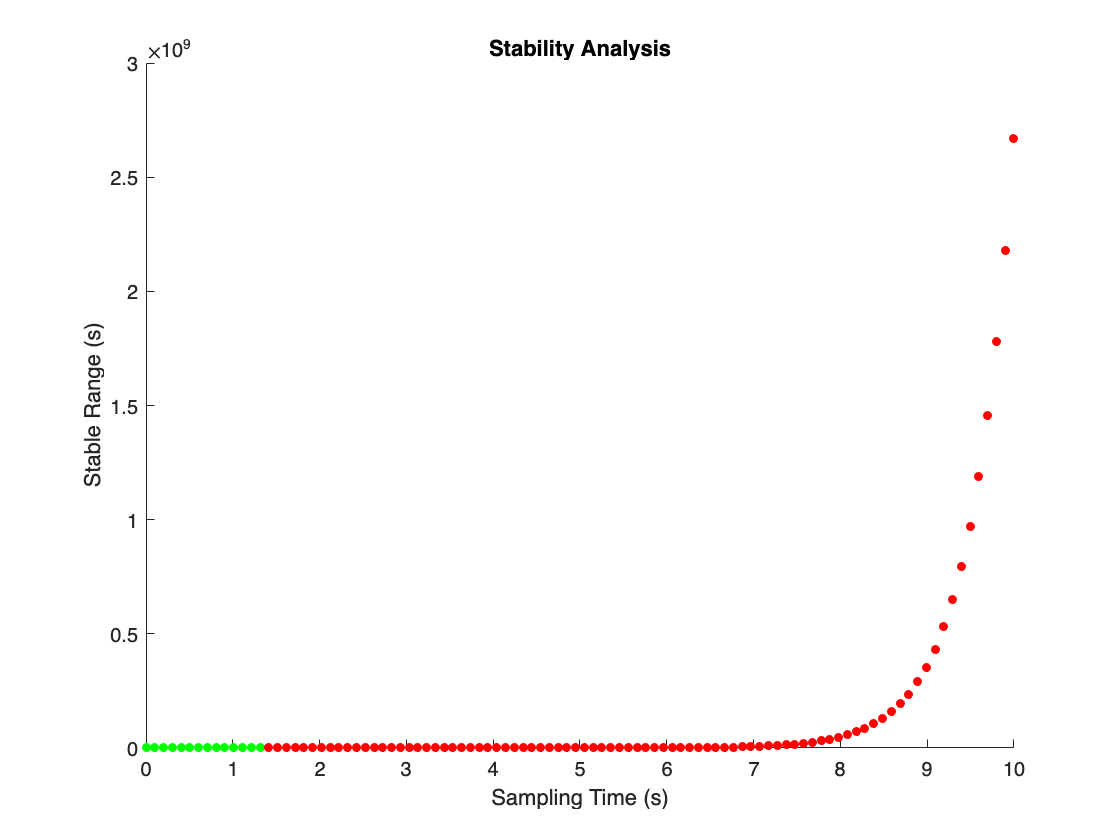

%Question1
%Question1-1
a= 5;
b= 3;
c= 1;
A=[a-b, 0.5-c; 0, 1];
B = [0; 1];
p1 = [-1+2j, -1-2j];
p2 = [-1, -2];
p3 = [1, 2];

%finding Ki
K1 = place(A, B, p1);
Acl1 = A - B*K1;
K2 = place(A, B, p2);
Acl2 = A - B*K2;
K3 = place(A, B, p3);
Acl3 = A - B*K3;

%Question1-2
% compute eigenvalues of Acl
eigAcl1 = eig(Acl1);
eigAcl2 = eig(Acl2);
eigAcl3 = eig(Acl3);

% check stability for different sampling times
numSamples = 100; % number of sampling times to test
maxTime = 10; % maximum sampling time to test
hVals = linspace(0.001, maxTime, numSamples); % generate sampling times to test
stableRanges = zeros(numSamples, 2); % initialize matrix to store stable ranges

%  figure; % create a new figure
%  hold on; % allow multiple plots in the same figure
maxsamplevalue1 = 0;
maxsamplevalue2 = 0;
maxsamplevalue3 = 0;

figure()
hold on 
for i = 1:numSamples
    h = hVals(i);
    F = expm(A*h);
    G = (expm(A*h) - eye(size(A)))/A * B;
    Acl1d = F - G * K1;
    eigAcl1d = eig(Acl1d);
    if max(abs(eigAcl1d) <1)
        scatter(h, max(abs(eigAcl1d)), 20, 'g', 'filled'); % green points for stable ranges
        maxsamplevalue1 = h;
    else
        scatter(h, max(abs(eigAcl1d)), 20, 'r', 'filled'); % red points for unstable ranges
    end
end
xlabel('Sampling Time (s)');
ylabel('Stable Range (s)');
title('Stability Analysis');

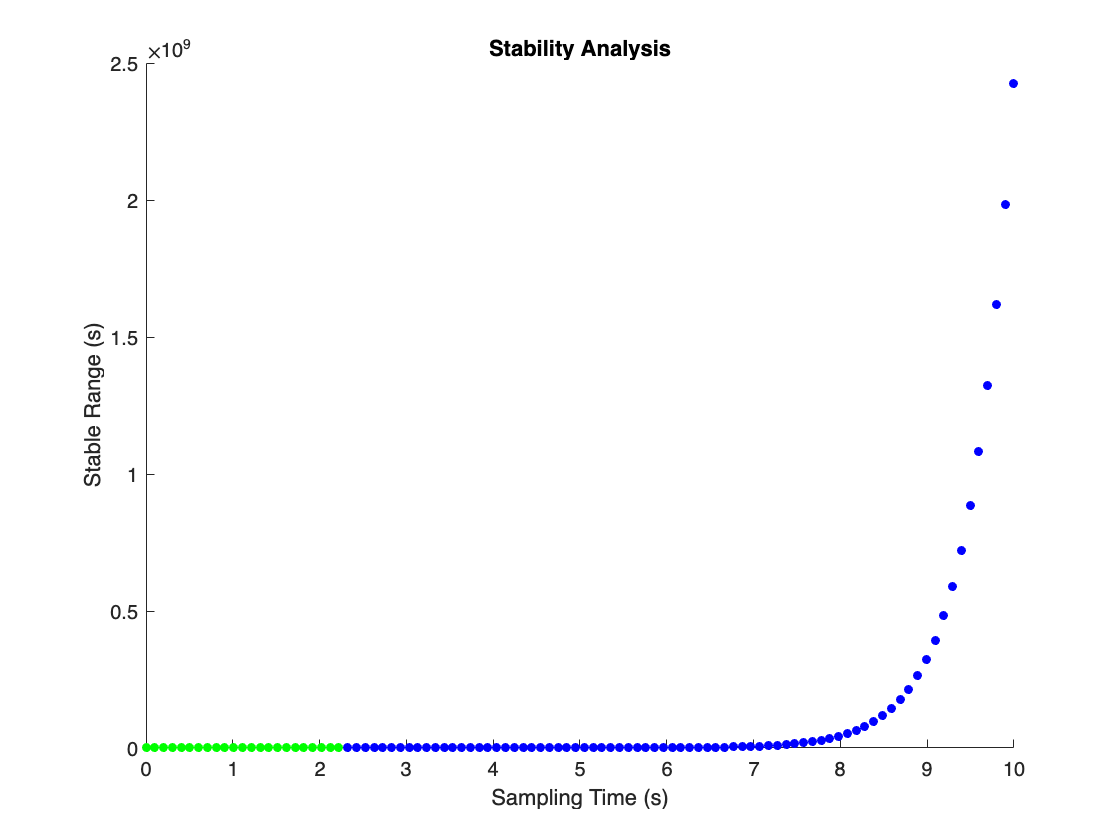


figure()
hold on 
for i = 1:numSamples
    h = hVals(i);
    F = expm(A*h);
    G = (expm(A*h) - eye(size(A)))/A * B;
    Acl2d = F - G * K2;
    eigAcl2d = eig(Acl2d);
    if max(abs(eigAcl2d) <1)
        scatter(h, max(abs(eigAcl2d)), 20, 'g', 'filled'); % green points for stable ranges
        maxsamplevalue2 = h;
    else
        scatter(h, max(abs(eigAcl2d)), 20, 'b', 'filled'); % blue points for unstable ranges
    end
end
xlabel('Sampling Time (s)');
ylabel('Stable Range (s)');
title('Stability Analysis');

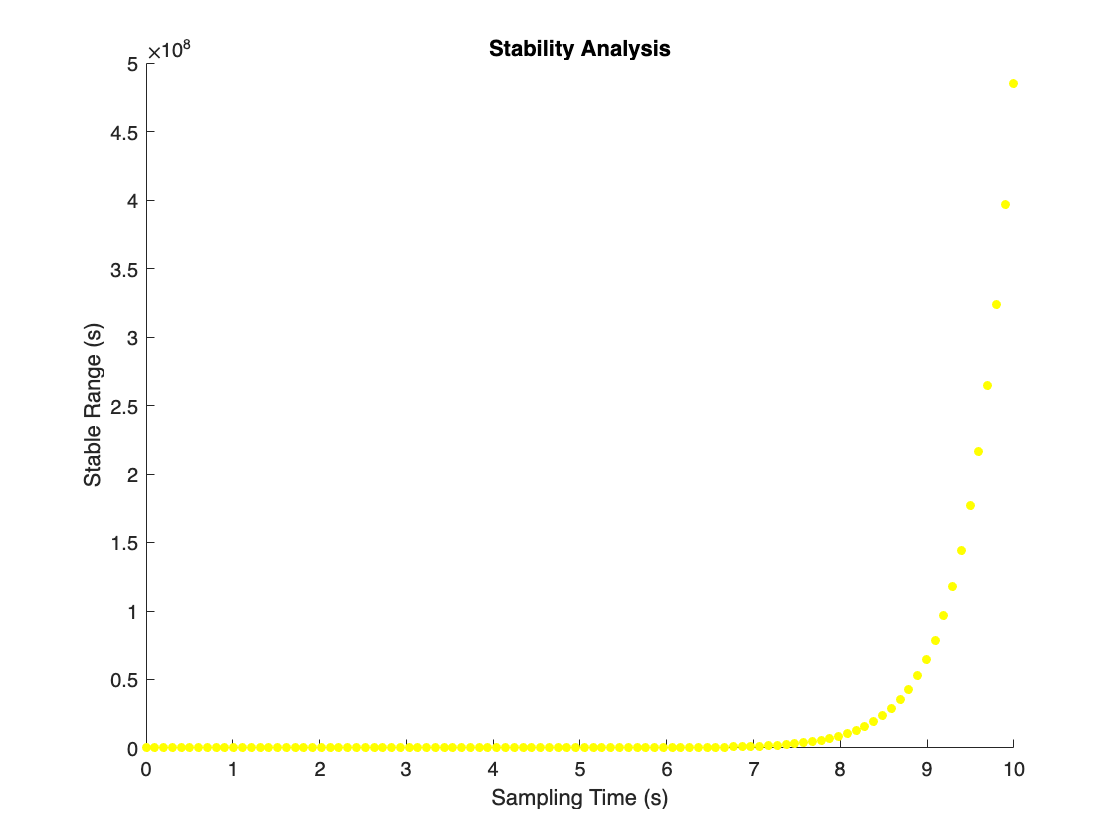


figure()
hold on
for i = 1:numSamples
    h = hVals(i);
    F = expm(A*h);
    G = (expm(A*h) - eye(size(A)))/A * B;
    Acl3d = F - G * K3;
    eigAcl3d = eig(Acl3d);
    if max(abs(eigAcl3d) <1)
        scatter(h, max(abs(eigAcl3d)), 20, 'g', 'filled'); % green points for stable ranges
        maxsamplevalue3 = h;
    else
        scatter(h, max(abs(eigAcl3d)), 20, 'y', 'filled'); % yellow points for unstable ranges
    end
end
%maxsamplevalue1 = 1.3140
%maxsamplevalue2 = 2.2230
%maxsamplevalue3 = 0
%It is observed that the ranges of sampling times for which the
%sampled-data system is stable for each controllers are ...
xlabel('Sampling Time (s)');
ylabel('Stable Range (s)');
title('Stability Analysis');


doc matlab.internal.richeditor.openAndConvert
